# Experiment with TCNpathToEEG model

## Load data

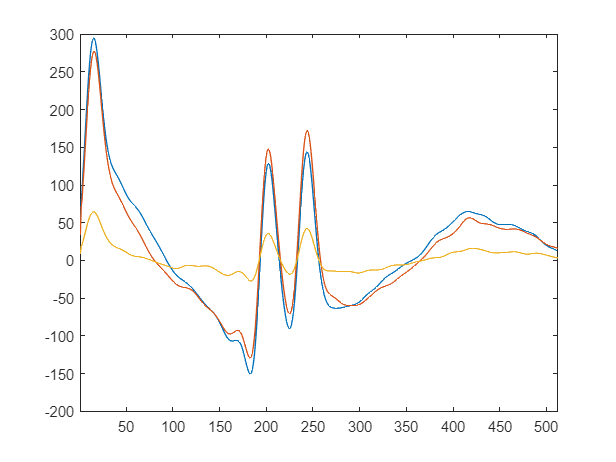

XTrain = load(fullfile('DataSet','HyperparameterSearch','Train','XSearchTrain.mat')).XSearchTrain;
YTrain = load(fullfile('DataSet','HyperparameterSearch','Train','YSearchTrain.mat')).YSearchTrain;

XTest = load(fullfile('DataSet','HyperparameterSearch','Test','XSearchTest.mat')).XSearchTest;
YTest = load(fullfile('DataSet','HyperparameterSearch','Test','YSearchTest.mat')).YSearchTest;

trainDs = {XTrain, YTrain};
testDs = {XTest, YTest};

figure;i = 1;
plot(XTrain{i}');
xlim([1 size(XTrain{i},2)]);

## Hyper-parameter search

|=================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |   numFilters |   filterSize |    numBlocks |     poolSize | miniBatchSize| learningrate |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |              |              |
|=================================================================================================================================================================|
|    1 | Best   |    0.082767 |      168.78 |    0.082767 |    0.082767 |            2 |           25 |            3 |           14 |           27 |     0.010709 |
|    2 | Accept |    0.083097 |      124.84 |    0.082767 |    0.082767 |           15 |           19 |            4 |           32 |           47 |   0.00037259 |
|    3 | Accept 

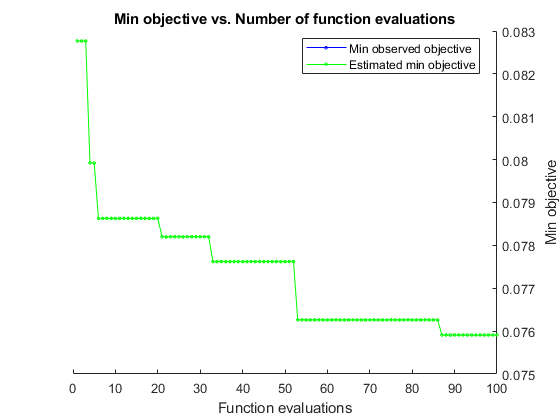


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 100 reached.
Total function evaluations: 100
Total elapsed time: 13980.4882 seconds
Total objective function evaluation time: 13913.4968

Best observed feasible point:
    numFilters    filterSize    numBlocks    poolSize    miniBatchSize    learningrate
    __________    __________    _________    ________    _____________    ____________

        29            22            5           19            109          0.0022342  

Observed objective function value = 0.07591
Estimated objective function value = 0.07591
Function evaluation time = 242.3098

Best estimated feasible point (according to models):
    numFilters    filterSize    n

maxEpochs = 30;
optimVars = [
    %numFilters, filterSize, numBlocks, miniBatchSize,learningrate,poolSize

    optimizableVariable('numFilters',[2 32],'Type','integer')
    optimizableVariable('filterSize',[3 33],'Type','integer')
    optimizableVariable('numBlocks',[1 5],'Type','integer')
    optimizableVariable('poolSize',[3 33],'Type','integer')
    optimizableVariable('miniBatchSize',[8 128],'Type','integer')    
    optimizableVariable('learningrate',[1e-4 1e-1],'Type','real',"Transform","log")];

objectFunction = objectFunctionCNN1d(trainDs, testDs,  maxEpochs);
    
% optimizer
BayesObject = bayesopt( objectFunction,             optimVars, ...
                        'MaxTime',                  24*60*60, ...
                        'Verbose',                  1,...
                        "UseParallel",              false,...
                        'IsObjectiveDeterministic', true, ...
                        'ParallelMethod',           "clipped-model-prediction",...
                        'MaxObjectiveEvaluations',  100,...
                        'ExplorationRatio',         0.6,...
                        'AcquisitionFunctionName', 'expected-improvement-per-second-plus');

optVars = bestPoint(BayesObject);

save("HyperParameterSearch\OptVars\CNN1doptVars.mat","optVars","-mat");

    % Evaluate and train the network with the optimal parameters
[valError,~,net, YPred, YTest] = BayesObject.ObjectiveFcn(optVars,1);

TX = {};
for k = 1:numel(testDs)
    TX{end+1} = testDs{k}{1};
end


TY = [];
Y = [];
YTest = YTest.';
for k = 1:numel(testDs{1})
    TY = [TY;YTest{k}];
    Y = [Y;YPred{k}];
end

confusionchart(TY(:),Y(:),'Normalization','column-normalized');